Consider the following optimization problem:


$$\left\lbrace \begin{array}{ll}
\textrm{minimize} & -x_1^2 +2x_1 +x_2^2 -2x_2 \\
s\ldotp t & x_1^2 -4\le 0\\
\; & x_2^2 -4\le 0
\end{array}\right.$$


close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

**a) Do global optimal solutions exist? Why?**

On this problem, we have an objective function with Q indefinite and for the existence of the global optimal we can apply the Eaves theorem. 


$$\left\lbrace \begin{array}{ll}
\textrm{minimize} & \frac{1}{2}x^T Q\;x+q^T x\\
s\ldotp t & A\;x\le b
\end{array}\right.$$


The recession cone $\Omega$ is $\textrm{rec}\left(\Omega \right)=\left\lbrace d:A\;d\le 0\right\rbrace$

There exists a global optimum for (P) if and only if:

- 
$$d^T Q\;d\ge 0\;;\forall d\;\epsilon \;\textrm{rec}\left(\Omega \right)$$


- $d^T \left(Q\;x+q\right)\ge 0\;;\forall x\;\epsilon \;\Omega \;\textrm{and}\;\forall d\;\epsilon \;\textrm{rec}\left(\Omega \right)$ such that $d^T Q\;d=0$

The problem is bounded, so the Theorem is satisfied and the answer is yes, the global optimal solution exist.

**b) Is it a convex problem? Why?**

It is a quadratic optimization problem and to prove that it is a convex optimization problem we need to show that both the objective function and the constraints are satisfy convexity properties:

- Objective Function: $f\left(x\right)=-x_1^2 +2x_1 +x_2^2 -2x_2$  

The objective function is quadratic convex minimization of the form: $f\left(x\right)=\frac{1}{2}x^T Q\;x+q^T x+b$ . To prove convexity, we need to show that the Hessian matrix Q is positive semidefinite. A matrix Q is positive semidefinite if the eigenvalues of Q are non-negative. 

- Constraints: 

-     
$$g_1 \left(x\right)=x_1^2 -4\le 0$$
 

-     
$$g_2 \left(x\right)=x_2^2 -4\le 0$$


The constraints in a quadratic convex minimization is presented on the form: $g_i \left(x\right)=\frac{1}{2}x^T A_i x+{a_i }^T x+c_i \le 0\;;\;\forall i=1,\ldotp \ldotp \ldotp ,m$  . To prove convexity, we need to show that the Hessian matrices $A_i$ are positive semidefinite.

% Objective Function
Q = [-4 0
      0 4];

% Inequality Constraints
A1 = [4 0
      0 0];

A2 = [0 0
      0 4];

fprintf('Eigen Values Objective Function:');

Eigen Values Objective Function:

display(eig(Q));

    -4
     4



fprintf('Eigen Values Contraints 1:');

Eigen Values Contraints 1:

display(eig(A1));

     0
     4



fprintf('Eigen Values Contraints 2:');

Eigen Values Contraints 2:

display(eig(A2));

     0
     4



In convex optimization, the objective functions should be concave and the constraints should define convex sets. However, the problem is represented has a concave objective function and convex contraints, which still qualifies it as a convex problem. Therefore, the given problem is a convex optimization problem.

% Definition of objective function and constraints
objective_function = @(x1,x2) -x1.^2 + 2.*x1 + x2.^2 - 2.*x2;
constraint_1 = @(x1) real(sqrt(4 - x1.^2));
constraint_2 = @(x2) real(sqrt(4 - x2.^2));

% Create a grid of x1 and x2 values
x1 = linspace(-4, 4, 100);
x2 = linspace(-4, 4, 100);
[X1, X2] = meshgrid(x1, x2);

% Evaluate the objective function and constraints on the grid
X3 = objective_function(X1, X2);
C1 = constraint_1(x1);
C2 = constraint_2(x2);

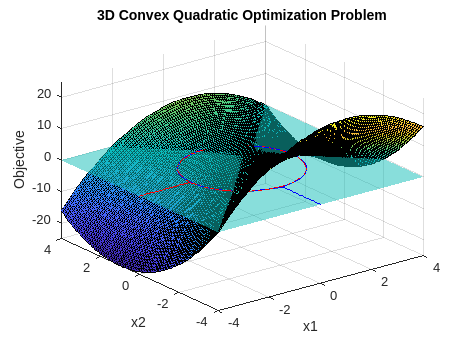

% Create a 3D plot
figure;
surf(X1, X2, X3);
hold on;
plot3(x1, C1, zeros(size(x1)), 'r-');
plot3(x1, -C1, zeros(size(x1)), 'r-');
surf(X1, X2, zeros(size(X3)), 'FaceAlpha', 0.5, 'EdgeColor', 'none');
plot3(C2, x2, zeros(size(x2)), 'b-');
plot3(-C2, x2, zeros(size(x2)), 'b-');

% Set labels and title
xlabel('x1');
ylabel('x2');
zlabel('Objective');
title('3D Convex Quadratic Optimization Problem');

% Show the grid on the plot
grid on;

% Adjust the plot view for better visibility
view(3);

% Adjust the plot limits if needed
xlim([-4 4]);
ylim([-4 4]);
hold off

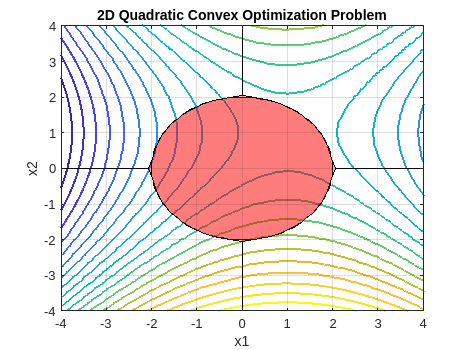

% Plot the objective function
figure;
contour(X1, X2, X3, 20, 'LineWidth', 1.5);
hold on;

% Plot the feasible region

fill([x1 fliplr(x1)], [C1 fliplr(-C1)], 'r', 'FaceAlpha', 0.3);
fill([C2 fliplr(-C2)],[x2 fliplr(x2)], 'r', 'FaceAlpha', 0.3);

% Set labels and title
xlabel('x1');
ylabel('x2');
title('2D Quadratic Convex Optimization Problem');

% Show the grid on the plot
grid on;

% Adjust the plot limits if needed
xlim([-4 4]);
ylim([-4 4]);

% Display the plot
hold off

**c) Does the Abadie constraints qualification hold in any feasible point? Why?**

We need to check the Abadie Second-Order condition to ensure the existence of a Karuch-Kuhn-Tucker point (which is a point that satisfies the KKT conditions).

Theorem - Sufficient conditions for ACQ

- (Linear independence of the gradient of active constraints): If $\bar{x} \;\epsilon \;\Omega$ and the vectors are independent, then ACQ holds at $\bar{x}$:


$$\left\lbrace \begin{array}{ll}
\nabla g_i \left(\bar{x} \right) & \textrm{for}\;i\;\epsilon \;A\left(\bar{x} \right)\\
\nabla h_j \left(\bar{x} \right) & \textrm{for}\;j=1,\ldotp \ldotp \ldotp ,p
\end{array}\right.$$


We need to solve the optimization problem and examine the KKT conditions: 

- Direction wich is feasible, $\nabla f\left(x\right)+\sum_{i=1}^m \lambda_i \nabla g_i \left(x\right)+\sum_{j=1}^p \mu_j \nabla h_j \left(x\right)$

- Feasible, $g\left(x\right)\le 0\;;h\left(x\right)=0$

- Complement slackness, $\lambda_i \left(g_i \left(x\right)\right)=0$

- Lagrange non-negativity $\lambda \ge 0$

On this exercise the conditions are as follows:


$$\left\lbrace \begin{array}{ll}
-2x_1 +2+2\lambda_1 x_1  & =0\\
2x_2 -2+2\lambda_2 x_2  & =0\\
x_1^2 -4 & \le 0\\
x_2^2 -4 & \le 0\\
\lambda_1 \left(x_1^2 -4\right) & =0\\
\lambda_2 \left(x_2^2 -4\right) & =0\\
\lambda_1  & \ge 0\\
\lambda_2  & \ge 0
\end{array}\right.$$


From the complementary slackness conditions, we can observe that is a constraints is inactive(not-binding), the corresponding Lagrange multiplier is zero. Therefore, is $\lambda_1 >0$ that $x_1^2 -4\le 0$ is an active constraint, and if $\lambda_2 >0$ that $x_2^2 -4\le 0$  is an active contraint.

With this observations, we can conclude that the Abadie Constraint Qualification holds at any feasible point for the given optimization problem.

**d) Is the point (0, 0) a local minimum? Why?**

We need to understand the function at that point $x^{\star } =\left(0,0\right)$ and examine the behavior of the objective function in the vicinity of that point. 

The objective function is $f\left(x\right)=-x_1^2 +2x_1 +x_2^2 -2x_2$ . Let-s evaluate at point $x^{\star } =\left(0,0\right)$

fprintf('Objective Function at (0,0) : %i',objective_function(0,0));

Objective Function at (0,0) : 0


$$f\left(0,0\right)=-{\left(0\right)}_1^2 +2{\left(0\right)}_1 +{\left(0\right)}_2^2 -2{\left(0\right)}_2 =0$$


We need to check the second-order partial derivates of the objective function. $f_{\textrm{xx}} =-2\;\;;\;\;f_{\textrm{xy}} =0\;\;\;;\;\;\;f_{\textrm{yx}} =0\;\;\;;\;\;\;f_{\textrm{yy}} =2\;\;$We have a mixed second-order partial derivatives. 

H = [-2 0
      0 2];
fprintf('Determinant: %i', det(H));

Determinant: -4

The Determinant of the Hessian Matrix is negative. Therefore, the Hessian matrix is not positive definite, and we cannot conclude that the point (0,0) is a local minimum based on the second-order sufficient condition.

**e) Find all the solutions of the KKT system.**

As we see before, the KKT system is as follow:


$$\left\lbrace \begin{array}{ll}
-2x_1 +2+2\lambda_1 x_1  & =0\\
2x_2 -2+2\lambda_2 x_2  & =0\\
x_1^2 -4 & \le 0\\
x_2^2 -4 & \le 0\\
\lambda_1 \left(x_1^2 -4\right) & =0\\
\lambda_2 \left(x_2^2 -4\right) & =0\\
\lambda_1  & \ge 0\\
\lambda_2  & \ge 0
\end{array}\right.$$
 

syms x1 x2 lambda1 lambda2
equations = [-2*x1+2+2*lambda1*x1==0
            2*x2-2+2*lambda2*x2==0
            x1^2-4<=0
            x2^2-4<=0
            lambda1*(x1^2-4)==0
            lambda2*(x2^2-4)==0
            lambda1>=0
            lambda2>=0]

$$equations = \left(\begin{array}{c} 2\,\lambda_{1}\,x_{1}-2\,x_{1}+2=0\\ 2\,x_{2}+2\,\lambda_{2}\,x_{2}-2=0\\ {x_{1}}^{2}-4\leq 0\\ {x_{2}}^{2}-4\leq 0\\ \lambda_{1}\,\left({x_{1}}^{2}-4\right)=0\\ \lambda_{2}\,\left({x_{2}}^{2}-4\right)=0\\ 0\leq \lambda_{1}\\ 0\leq \lambda_{2} \end{array}\right)$$

% Compute analytic solution of a symbolic equation
solution = solve(equations,[sym('lambda1'),sym('lambda2'),sym('x1'),sym('x2')],...
    "Real",true,...
    "IgnoreAnalyticConstraints",true,...
    "IgnoreProperties",true);
% Display symbolic solution returned by solve
displaySymSolution(solution);

solution = struct with fields:
    lambda1: [3×1 sym]
    lambda2: [3×1 sym]
         x1: [3×1 sym]
         x2: [3×1 sym]


where


$$\left(\begin{array}{cccc} \lambda_{1}\left(1\right) & \lambda_{2}\left(1\right) & x_{1}\left(1\right) & x_{2}\left(1\right) \end{array}\right)=\left(\begin{array}{cccc} 0 & 0 & 1 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \lambda_{1}\left(2\right) & \lambda_{2}\left(2\right) & x_{1}\left(2\right) & x_{2}\left(2\right) \end{array}\right)=\left(\begin{array}{cccc} \frac{1}{2} & 0 & 2 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \lambda_{1}\left(3\right) & \lambda_{2}\left(3\right) & x_{1}\left(3\right) & x_{2}\left(3\right) \end{array}\right)=\left(\begin{array}{cccc} \frac{3}{2} & 0 & -2 & 1 \end{array}\right)$$


variables = [x1,x2,lambda1,lambda2];

[x1,x2,lambda1,lambda2] = solve(equations, variables)

$$x1 = \left(\begin{array}{c} 1\\ 2\\ -2 \end{array}\right)$$

$$x2 = \left(\begin{array}{c} 1\\ 1\\ 1 \end{array}\right)$$

$$lambda1 = \left(\begin{array}{c} 0\\ \frac{1}{2}\\ \frac{3}{2} \end{array}\right)$$

$$lambda2 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

**f) Find local minima and global minima.**

- Local minima

To find the local minima, we need to find the critical points of the objective function within the feasible region. These critical points occur where the gradient of the objective function is zero or undefined and lie within the feasible region. $\frac{\partial f}{\partial x_1 }=0\;\;;\;\;\frac{\partial f}{\partial x_2 }=0$


$$\begin{array}{l}
\nabla f\left(x\right)=\left(-2x_1 +2\;,\;2x_2 -2\right)=0\\
-2x_1 +2\;\;=\;0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;2x_2 -2=0\\
x_1 =1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x_2 =1
\end{array}$$


A = [-2 0
      0 2];
b = [-2
      2];

x_local = A\b;

Next, we need to check if the critical point lies within the feasible region. $x^{\star } =\left(1,1\right)$ satisfies both constraints: $g_1 \left(x\right)\le 0$ and $g_2 \left(x\right)\le 0$


$$\begin{array}{l}
x^{\star } =\left(1,1\right)\\
x_1^2 -4\le 0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x}_2^2 -4\le 0\\
\left(1\right)-4\le 0\;\;\textrm{constraint}\;\textrm{satisfied}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)-4\le 0\;\textrm{constraint}\;\textrm{satisfied}
\end{array}$$


if (x_local(1)^2-4<=0) && (x_local(2)^2-4<=0)
    fprintf("Local minima found: (%d %d)", x_local')
end

Local minima found: (1 1)

- Global minima

To find the global minima, we need to consider the boundary of the feasible region and check the objective function values at those points. $g_1 \left(x\right)=0$ and $g_2 \left(x\right)=0$


$$x_1^2 -4=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x_2^2 -4=0$$


syms x1 x2

% g1 = 0
equations = x1^2-4==0;
variables = [x1, x2];

[x, y] = solve(equations,variables);

M = [x  y];

% g2 = 0
equations = x2^2-4==0;
variables = [x1, x2];

[x, y] = solve(equations,variables);

M = [M
     x  y]

$$M = \left(\begin{array}{cc} -2 & 0\\ 2 & 0\\ 0 & -2\\ 0 & 2 \end{array}\right)$$

Now, we need to check the objective function values at those points M

n = size(M,1);
evaluation = zeros(n,1);
for i = 1:n     
    evaluation(i) = objective_function(M(i, 1), M(i, 2));
end

[~, i] = min(evaluation, [], 'all');

if (i)
    fprintf("Global minima found");
    display(M(i, :));
end

Global minima found

$$ans = \left(\begin{array}{cc} -2 & 0 \end{array}\right)$$

**g) Find the objective function and constraints of the Lagrangian dual problem.**

We can start with the Lagrangian Relaxation: $L\left(x,\lambda ,\mu \right)=f\left(x\right)+\sum_{i=1}^m \lambda_i g_i \left(x\right)+\sum_{j=1}^p \mu_j h_j \left(x\right)$

This original optimization problem with the form of Lagrangian Relaxation is as follows:


$$L\left(x_1 ,x_2 ,\lambda_1 ,\lambda_2 \right)=-x_1^2 +2x_1 +x_2^2 -2x_2 +\lambda_1 \left(x_1^2 -4\right)+\lambda_2 \left(x_2^2 -4\right)$$


syms x1 x2 lambda1 lambda2

% Define the Objective Function and the Constraints
objectiveFunction = -x1.^2 + 2.*x1 + x2.^2 - 2.*x2;
constraint1 = x1.^2 - 4;
constraint2 = x2.^2 - 4;

lagrangian = objectiveFunction + lambda1*(constraint1) + lambda2*(constraint2);

% Differentiate with respect to x1, x2, lambda1, lambda2
d_x1 = diff(lagrangian, x1);
d_x2 = diff(lagrangian, x2);
d_lambda1 = diff(lagrangian, lambda1);
d_lambda2 = diff(lagrangian, lambda2);

fprintf("Lagrangian Dual Optimizatio Problem");

Lagrangian Dual Optimizatio Problem

% Solve the Lagrangian Dual
equations = [d_x1 == 0
             d_x2 == 0
             d_lambda1 <= 0
             d_lambda2 <= 0
             lambda1>=0
             lambda2>=0]

$$equations = \left(\begin{array}{c} 2\,\lambda_{1}\,x_{1}-2\,x_{1}+2=0\\ 2\,x_{2}+2\,\lambda_{2}\,x_{2}-2=0\\ {x_{1}}^{2}-4\leq 0\\ {x_{2}}^{2}-4\leq 0\\ 0\leq \lambda_{1}\\ 0\leq \lambda_{2} \end{array}\right)$$


sol = solve(equations)

sol = struct with fields:
    lambda1: 0
    lambda2: 0
         x1: 1
         x2: 1
